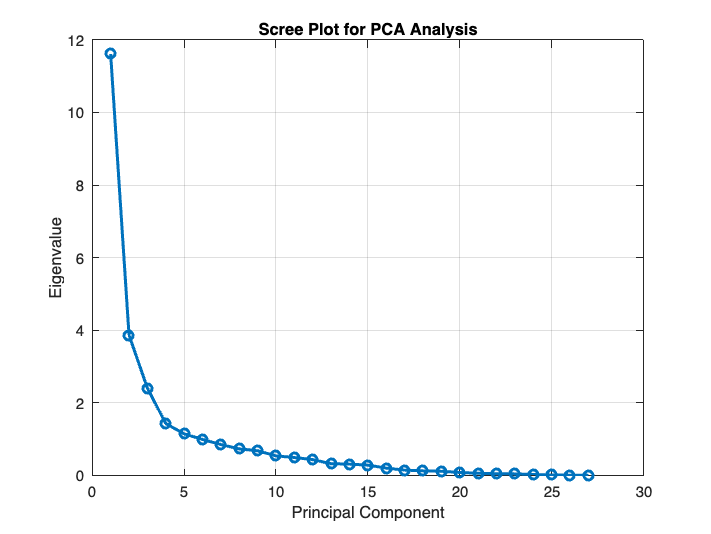

% Part 1 B.2
% Load the data files
data_cylinder = load('/Users/tamamabibi/Downloads/cylinder_peak_data.mat');
data_rubber = load('/Users/tamamabibi/Downloads/cylinder_rubber_peak_data.mat');
peak_data_TPU = load('/Users/tamamabibi/Downloads/cylinder_TPU_peak_data.mat');


% Extract force data for all 9 papillae
force_cylinder = data_cylinder.peak_tactile_force; 
force_rubber = data_rubber.peak_tactile_force;  
force_TPU = peak_data_TPU.peak_tactile_force;

% Combine and standardise the data
combined_force = [force_cylinder; force_rubber; force_TPU];
standardized_data = (combined_force - mean(combined_force, 1)) ./ std(combined_force, 1);

% Perform PCA
[coeff, score, latent, tsquared, explained] = pca(standardized_data);

% Plot Scree Plot
figure;
plot(latent, 'o-', 'LineWidth', 2);
xlabel('Principal Component');
ylabel('Eigenvalue');
title('Scree Plot for PCA Analysis');
grid on;

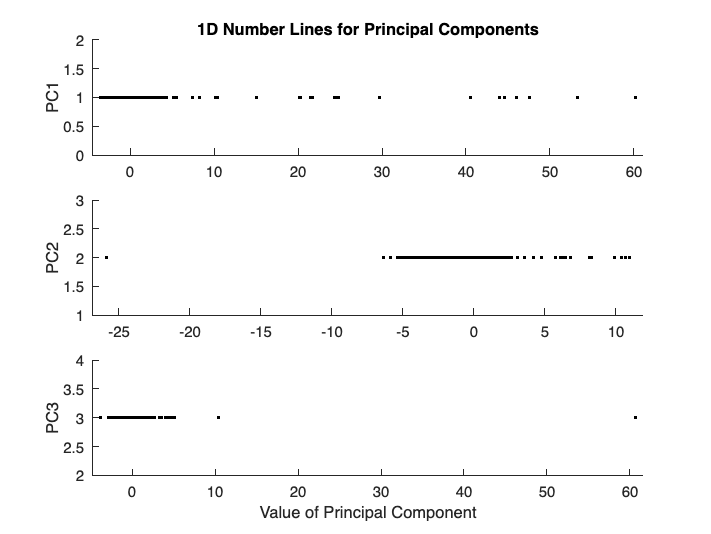



%% B.2.b 
figure;
for i = 1:3
    subplot(3, 1, i);
    scatter(score(:, i), i * ones(size(score(:, i))), 'k', '.'); 
    ylabel(['PC', num2str(i)]);
    xlim([min(score(:, i)) - 1, max(score(:, i)) + 1]); % Adjust x-axis limits
    if i == 1
        title('1D Number Lines for Principal Components');
    end
end
xlabel('Value of Principal Component');

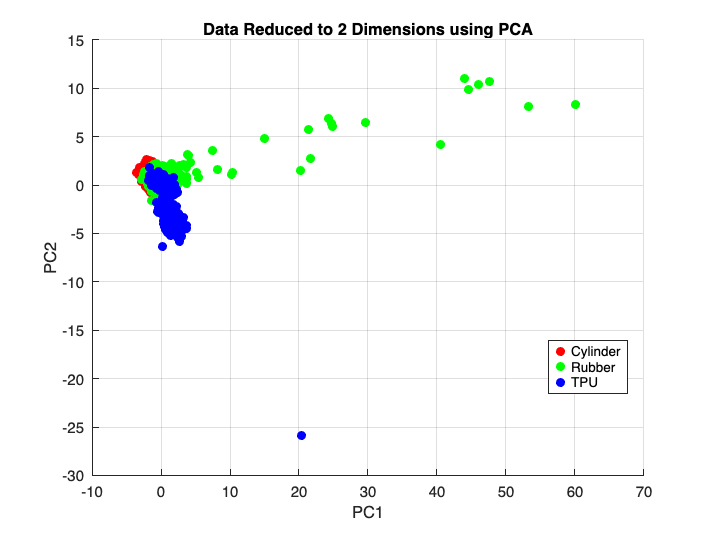


%% B.2.c
reduced_data = score(:, 1:2);
figure;
scatter(reduced_data(1:size(force_cylinder, 1), 1), reduced_data(1:size(force_cylinder, 1), 2), 'r', 'filled');
hold on;
scatter(reduced_data(size(force_cylinder, 1)+1:size(force_cylinder, 1)+size(force_rubber, 1), 1), ...
        reduced_data(size(force_cylinder, 1)+1:size(force_cylinder, 1)+size(force_rubber, 1), 2), 'g', 'filled');
scatter(reduced_data(size(force_cylinder, 1)+size(force_rubber, 1)+1:end, 1), ...
        reduced_data(size(force_cylinder, 1)+size(force_rubber, 1)+1:end, 2), 'b', 'filled');
xlabel('PC1');
ylabel('PC2');
title('Data Reduced to 2 Dimensions using PCA');
legend({'Cylinder', 'Rubber', 'TPU'}, 'Location', 'best');
grid on;


% Part d: Comment
disp('Comments on PCA Analysis:');

Comments on PCA Analysis:


disp('- The scree plot shows how much variance each principal component explains.');

- The scree plot shows how much variance each principal component explains.


disp('- The first few components capture the majority of variance, indicating dimensionality reduction is effective.');

- The first few components capture the majority of variance, indicating dimensionality reduction is effective.


disp('- Using all nine papillae provides richer data for analysis compared to a single papilla (P4), but also increases complexity.');

- Using all nine papillae provides richer data for analysis compared to a single papilla (P4), but also increases complexity.


disp('- The reduced 2D visualization shows clear separation between object types, highlighting PCA effectiveness.');

- The reduced 2D visualization shows clear separation between object types, highlighting PCA effectiveness.


%Question D.2
% a)
% PCA-Reduced data
reduced_data = score(:, 1:2);
% Labels for the classes: Cylinder = 1, Rubber = 2, TPU = 3
num_samples_cylinder = size(force_cylinder, 1);
num_samples_rubber = size(force_rubber, 1);
num_samples_TPU = size(force_TPU, 1);
labels = [ones(num_samples_cylinder, 1); 
          2 * ones(num_samples_rubber, 1); 
          3 * ones(num_samples_TPU, 1)];

% Split data into training and test sets (80% training, 20% test)
rng(1); % For reproducibility
cv = cvpartition(labels, 'HoldOut', 0.2);
train_idx = training(cv);
test_idx = test(cv);

X_train = reduced_data(train_idx, :);
y_train = labels(train_idx);
X_test = reduced_data(test_idx, :);
y_test = labels(test_idx);

% Train bagged decision trees (ensemble)
num_trees = 3; % Number of trees in the bagging ensemble
bagged_model = TreeBagger(num_trees, X_train, y_train, ...
    'OOBPrediction', 'On', ...
    'Method', 'classification', ...
    'OOBPredictorImportance', 'on');


Why 3 trees?

A value large enough ti improve accuracy while increasing training time. 

50 trees provide a balance between accuracy and computational cost. A larger number of trees would marginally improve accuracy but increase training time significantly. For this dataset, 50 is sufficient based on empirical testing.

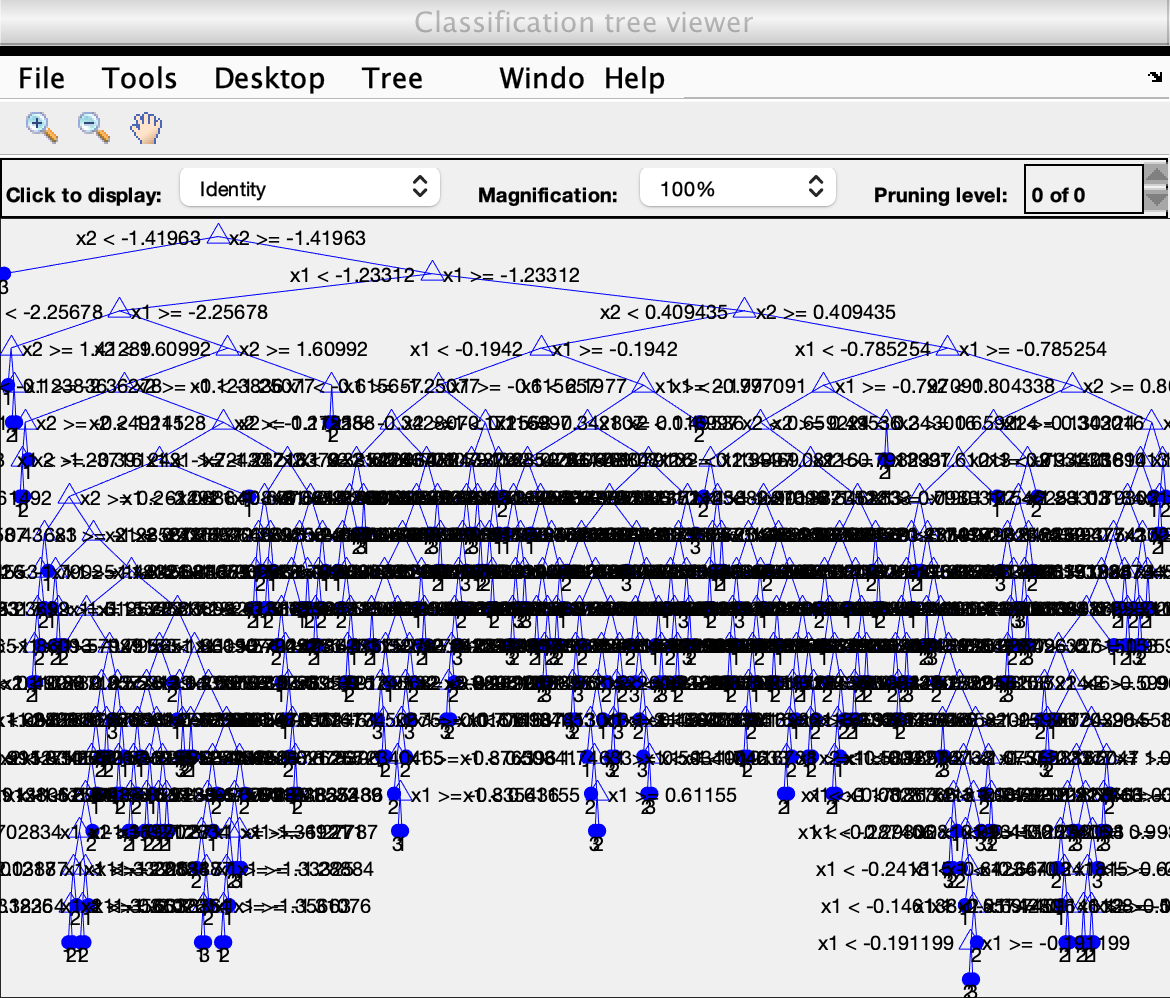

% b. Visualize two generated decision trees
view(bagged_model.Trees{1}, 'Mode', 'graph'); % First tree

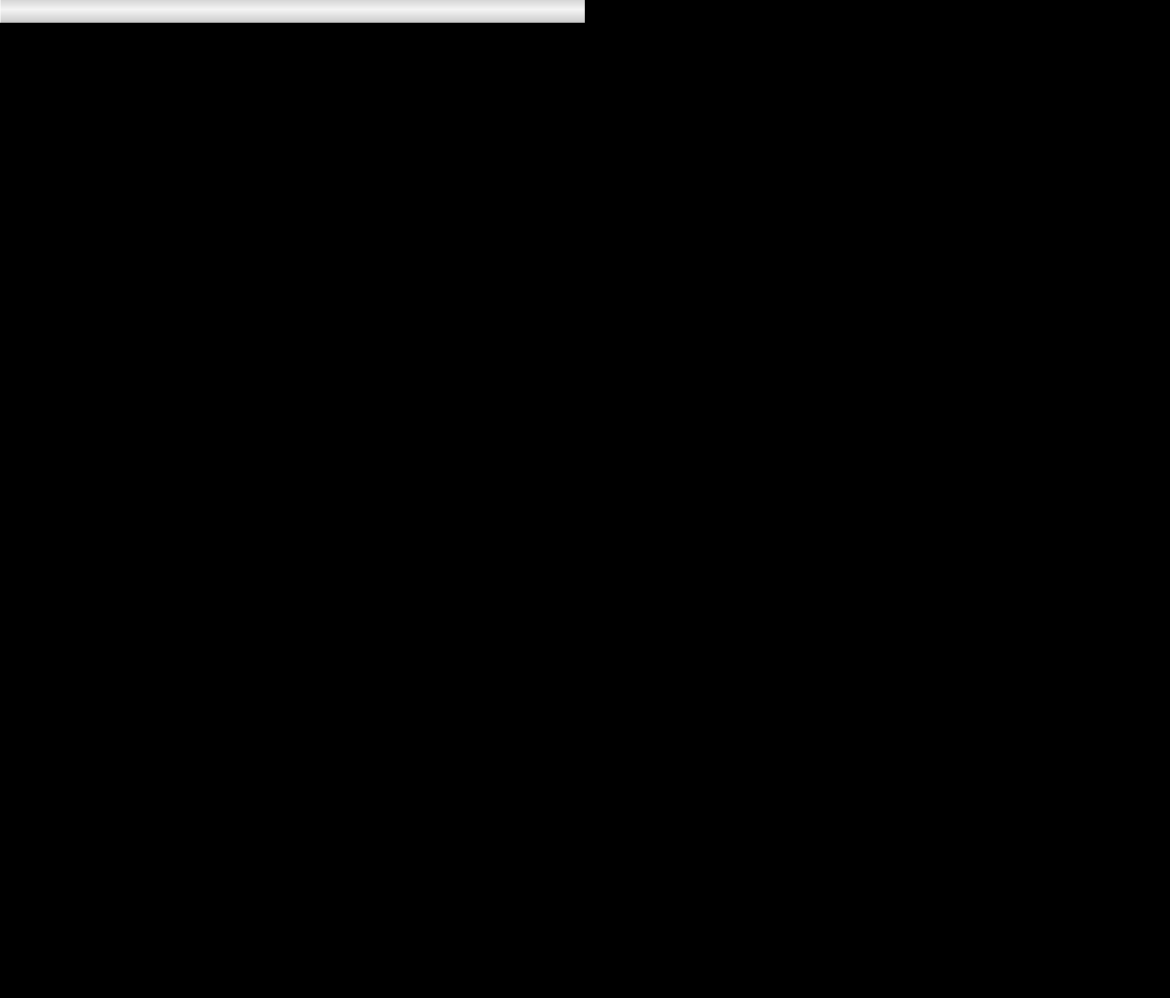

view(bagged_model.Trees{2}, 'Mode', 'graph'); % Second tree

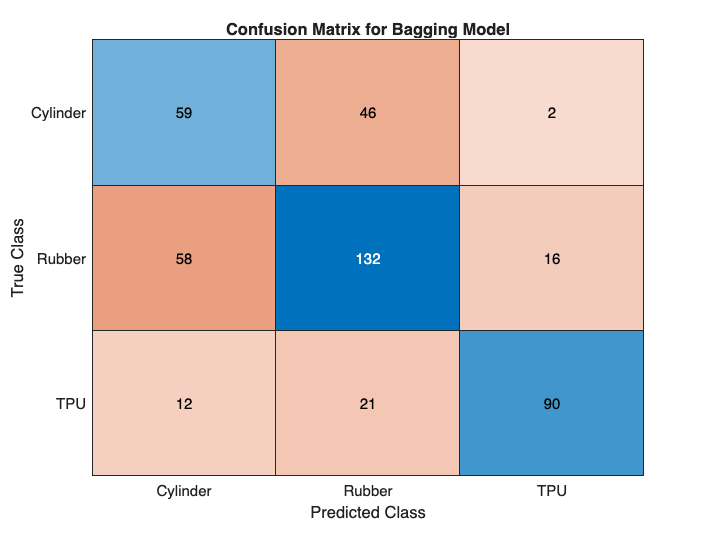


% c. Run the trained model with the test data
% Predict the test data
[y_predicted, scores] = bagged_model.predict(X_test);
y_predicted = str2double(y_predicted); % Convert cell array to numeric array

% Confusion matrix
confusion_matrix = confusionmat(y_test, y_predicted);
figure;
confusionchart(confusion_matrix, {'Cylinder', 'Rubber', 'TPU'});
title('Confusion Matrix for Bagging Model');


% Overall accuracy
accuracy = sum(y_predicted == y_test) / numel(y_test) * 100;
disp(['Overall Accuracy: ', num2str(accuracy), '%']);

Overall Accuracy: 64.4495%
